[https://kr.mathworks.com/help/nav/ref/lidarslam.addscan.html?searchHighlight=addscan&s_tid=srchtitle_addscan_1](https://kr.mathworks.com/help/nav/ref/lidarslam.addscan.html?searchHighlight=addscan&s_tid=srchtitle_addscan_1)

load('data2.mat');


scans = scans(1:20:end);

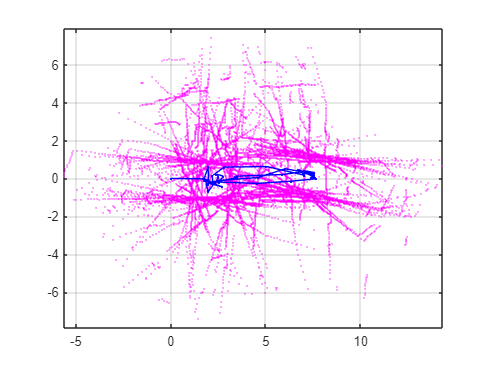

maxRange = 7; % meters
resolution = 20; % cells per meter

slamObj = lidarSLAM(resolution,maxRange);
slamObj.LoopClosureThreshold = 360;
slamObj.LoopClosureSearchRadius = 8;

for i = 1:numel(scans)

    addScan(slamObj,scans{i});
    
    if rem(i,10) == 0
        show(slamObj);
    end
end

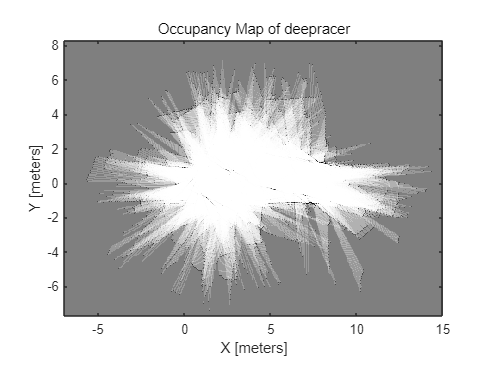


[scansSLAM,poses] = scansAndPoses(slamObj);
deepracerMap = buildMap(scansSLAM,poses,resolution,maxRange);
figure
show(deepracerMap)
title('Occupancy Map of deepracer')